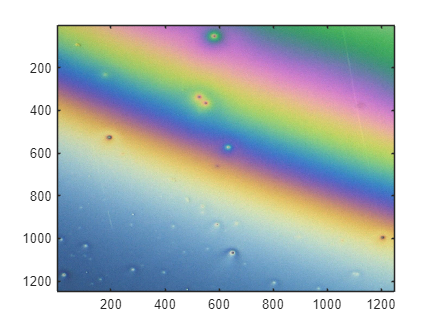

clear
clc
lim = 20; %扫描范围
index = 10;
test = imread('3.jpg');
image(test)

test = imrotate(test,-90);
load("rm_f.mat");

rgbmatrix(1,:) = rgbmatrix(1,:) * 0.85;

siz = size(test);
mat = nan(siz(1), siz(2));
for i = 1:siz(1)
    for j = 1:siz(2)
        r = double(test(i,j,1));
        g = double(test(i,j,2));
        b = double(test(i,j,3));
        mid = rect_mean_exclude_nan(mat,i,j,index);
%         if i == 1 && j == 1
%             mid = 400
%         end
        mat(i,j) = rgb2Thick(rgbmatrix,r,g,b,mid,lim);
    end
end

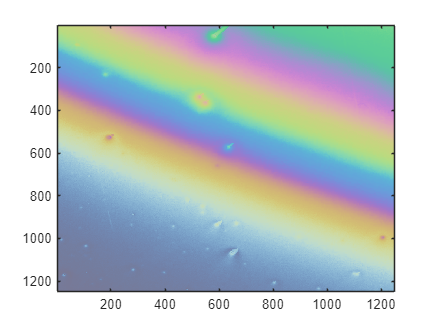

imagesc(imrotate(mat,90))
customCMap = uint8(rgbmatrix(:,min(mat,[],'all'):max(mat,[],'all'))');
colormap(customCMap);

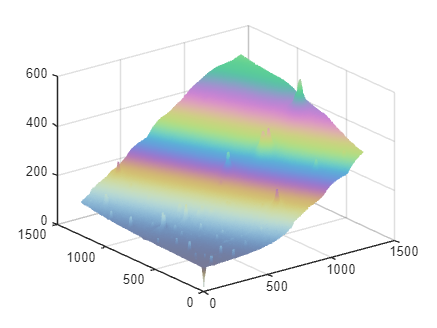

% colorbar
mesh(mat);

% h = fspecial("gaussian");
% ma = filter2(h,mat);
% mesh(ma)

% C = pagemtimes(reshape(rgbmatrix'/256,[],1,3),ones(1,100,3));
% image(imrotate(C,90))

function [thick] = rgb2Thick(rgbmatrix,y1,y2,y3,mid,lim)
    if isnan(mid)
        mid = 0;
    end
    start = max(1, mid - lim);
    endp = min(mid + lim, size(rgbmatrix,2));
    delta = (rgbmatrix(1,start)-y1)^2+(rgbmatrix(2,start)-y2)^2+(rgbmatrix(3,start)-y3)^2;
    res = 0;
    for i = start+1:endp
        delta0 = (rgbmatrix(1,i)-y1)^2+(rgbmatrix(2,i)-y2)^2+(rgbmatrix(3,i)-y3)^2;
        if delta0 < delta
            delta = delta0;
            res = i;
        end
    end
    thick = res;
    if thick == 0
        thick = mid;
    end
end
function [co] = rect_mean_exclude_nan(mat, x, y, i)
    if x == 1 && y == 1
        co = 0;
    else
        [m, n] = size(mat);  % 获取矩阵尺寸
    
        % 计算有效的矩形范围
        row_start = max(1, x - i);
        row_end   = min(m, x);
        col_start = max(1, y - i);
        col_end   = min(n, y);
    
        % 提取子矩阵
        submat = mat(row_start:row_end, col_start:col_end);
        co = int16(mean(submat(~isnan(submat))));
    end
end